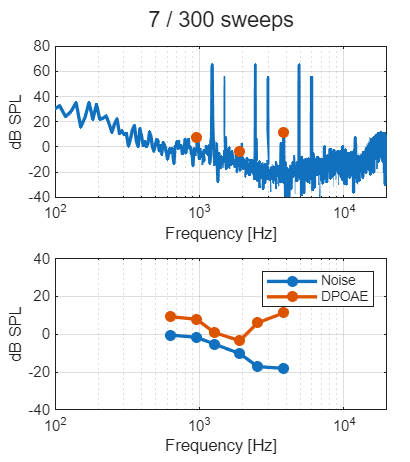

%% BY USING THIS SCRIPT, YOU ACCEPT THE FOLLOWING TERMS
%
% This script provides the basic underlying framework for measuring
% pure-tone distortion-product otoacoustic emissions (DPOAE) using the
% Titan Research Platform. The script supports the standard 2f1-f2
% protocol.
%
% This script is provided to illustrate the functionality of the Titan
% Research Platform. Interacoustics cannot aid the modification of the
% script to serve specific research needs, and such modification and the
% general use of the script is at your own responsibility.


clear


addpath(genpath('../Research-dependencies/'))

fs=44100;
Titan=Titan(fs);

load('TransducerSensIOWA')

%% Settings
ch=[1 2];
blockLength=4096;
filterCutOff=250;
filterOrder=2;

dBSPL=[65 55];
dBmaxSweepNoise=55;
dBOAEpassSNR=6;
fRatio=1.22;

frequencyAim = load("dpFrequenciesDummy.mat");
f2aim = frequencyAim.f2aim;
f2Idx = frequencyAim.f2Idx;
sz = size(f2Idx');

minSweeps=6;
maxSweeps=300;

dpResponse = zeros(sz);
freqData = zeros(sz);
dpRespData = zeros(sz);

%% Initialize
t=(0:blockLength-1).'/fs;
freqFFT=(0:blockLength/2-1).'*fs/blockLength;
fftScale=2/(sqrt(2)*blockLength);
micSens=ppval(ppMicSens,freqFFT);

pTarget=2e-5*10.^(dBSPL/20);

[bFilter,aFilter]=butter(filterOrder,filterCutOff*2/fs,'high');
Hfilter=freqz(bFilter,aFilter,blockLength/2,fs);

%% Plots
fig=figure('units','normalized','outerposition',[0.3 0.1 0.4 0.8]);
tiledlayout(2,1,'padding','compact','tilespacing','compact')
sgtitle(fig,['0 / ' num2str(maxSweeps) ' sweeps']);

nexttile
lnSpectrum=semilogx(1,'linewidth',2);hold on
lnDPmarker=semilogx(1,'.','markersize',20);
xlim([100 20000]);ylim([-40 80])
xlabel('Frequency [Hz]');ylabel('dB SPL')
grid

nexttile
lnDPgramNoise=semilogx(0,'.-','markersize',20,'linewidth',2);hold on
lnDPgram=semilogx(0,'.-','markersize',20,'linewidth',2);
xlim([100 20000]);ylim([-40 40])
xlabel('Frequency [Hz]');ylabel('dB SPL')
legend('Noise','DPOAE')
grid
drawnow

%% Measurement
timerVal = tic;
Titan.InitializePressure();
for nFreqSet=1:size(f2Idx,1)
    f2IdxVec = f2Idx(nFreqSet,:);
    f2IdxVec = f2IdxVec(f2IdxVec~=0);

    numFreqs(nFreqSet) = length(f2IdxVec);

    idxFreq = round((f2aim(f2IdxVec,1)*blockLength/fs+1).*[1/fRatio 1]);
    idxFreq(:,3)=2*idxFreq(:,1)-idxFreq(:,2);
    freq=reshape(freqFFT(idxFreq),size(idxFreq));

    stimulus(:,:,nFreqSet) = generateStimulus(1:numFreqs(nFreqSet), freq, t);

    % Find noise indices and filter out common elements with frequency
    % index matrix
    idxNoise = [];

    for i = numFreqs(nFreqSet):-1:1
        tempVec = [round(idxFreq(i,3).^2./idxFreq(i,1))+1:idxFreq(i,3)-1, idxFreq(i,3)+1:idxFreq(i,1)-1];
        idxCommon = intersect(idxFreq, tempVec);
        if ~isempty(idxCommon); tempVec = setxor(tempVec, idxCommon); end
        idxNoise(i,:) = [tempVec, zeros(1,size(idxNoise, 2)-size(tempVec, 2))];
    end


    % Adjust level
    spkrSens=[ppval(ppSpkrSens(ch(1)),freq(numFreqs(nFreqSet), 1)) ppval(ppSpkrSens(ch(2)),freq(numFreqs(nFreqSet), 2))];
    levelStart=pTarget./abs(spkrSens);
    Titan.StartStimulation(sqrt(2)*levelStart.*stimulus(:,:,nFreqSet),ch);
    Titan.LogResponses(2);

    [~,initFilter]=filter(bFilter,aFilter,Titan.response{end}(:,1));
    [responseAdjust,initFilter]=filter(bFilter,aFilter,Titan.response{end}(:,2),initFilter);
    fftResponseAdjust=fftScale*dft(responseAdjust)./(Hfilter.*micSens);
    
    %Level adjusted for multi frequency
    primaryResponses = abs(fftResponseAdjust(idxFreq(:,1:2)));
    if all(size(primaryResponses) == [2 1]); primaryResponses = primaryResponses'; end
    levelPerTone = levelStart.*pTarget ./ primaryResponses;
    level = mean(levelPerTone,1);  % average across tones

    calibratedStimulus(:,:,nFreqSet) = generateStimulus(1:numFreqs(nFreqSet), freq, t, levelPerTone);

    if max(dbspl(spkrSens.*level))>90
        error('Pressure threshold exceeded.')
    end

    % Measure DPOAE
    Titan.StartStimulation(calibratedStimulus(:,:,nFreqSet),ch);
    Titan.StartLogging();

    nBlock=1;
    nSweep=1;
    while 1
        Titan.Wait(nBlock)

        response{nFreqSet}(:,nBlock)=Titan.response{end}(:,nBlock);
        if nBlock==1
            [~,initFilter]=filter(bFilter,aFilter,response{nFreqSet}(:,nBlock));
        else
            [responseFiltTmp(:,mod(nBlock,2)+1),initFilter]=filter(bFilter,aFilter,response{nFreqSet}(:,nBlock),initFilter);
            if mod(nBlock,2)
                fftResponseNoise=dft(responseFiltTmp);
                rmsSweepNoise=sqrt(2/blockLength^2*sum(abs(diff(fftResponseNoise(2:end,:),1,2)./sqrt(2)./(micSens(2:end))).^2));
                if dbspl(rmsSweepNoise)>dBmaxSweepNoise
                    nBlock=nBlock+1;
                    continue
                end

                meanResponseFilt{nFreqSet}(:,nSweep)=mean(responseFiltTmp,2);
                fftResponse(:,nFreqSet)=fftScale*dft(mean(meanResponseFilt{nFreqSet},2))./(Hfilter.*micSens);

                dpResponse(1:numFreqs(nFreqSet),nFreqSet)=fftResponse(idxFreq(:,3),nFreqSet);
                for i = 1:numFreqs(nFreqSet)
                    idxNoiseVec = idxNoise(i,:);
                    idxNoiseVec = idxNoiseVec(idxNoiseVec~=0);
                    noiseFloor(i,nFreqSet)=mean(abs(fftResponse(idxNoiseVec,nFreqSet)));
                end
                
                idxFreqDP(1:numFreqs(nFreqSet),nFreqSet) = idxFreq(:,3);
                freqData(1:numFreqs(nFreqSet),nFreqSet) = freq(:,3);
                dpRespData(1:numFreqs(nFreqSet),nFreqSet) = dpResponse(1:numFreqs(nFreqSet),nFreqSet);

                freqDataVec = reshape(freqData, [], 1);
                freqDataVec = freqDataVec(freqDataVec~=0);
                dpRespDataVec = reshape(dpRespData, [], 1);
                dpRespDataVec = dbspl(dpRespDataVec(dpRespDataVec~=0));
                nfVec = reshape(noiseFloor, [], 1);
                nfVec = nfVec(nfVec~=0);
                nfDataVec = dbspl(nfVec);

                [~, orderIndex] = sort(freqDataVec);

                set(lnSpectrum,'xdata',freqFFT,'ydata',dbspl(fftResponse(:,nFreqSet)));
                set(lnDPmarker,'xdata',freqFFT(idxFreq(:,3)),'ydata',dbspl(fftResponse(idxFreq(:,3),nFreqSet)));
                set(lnDPgram,'xdata',freqDataVec(orderIndex),'ydata',dpRespDataVec(orderIndex))
                set(lnDPgramNoise,'xdata',freqDataVec(orderIndex),'ydata',nfDataVec(orderIndex))
                sgtitle(fig,[num2str(nSweep) ' / ' num2str(maxSweeps) ' sweeps'])
                drawnow limitrate
                
                dpResponseCurrent = dpResponse(:,nFreqSet);
                dpResponseCurrent = dpResponseCurrent(dpResponseCurrent~=0);
                noiseFloorCurrent = noiseFloor(:,nFreqSet);
                noiseFloorCurrent = noiseFloorCurrent(noiseFloorCurrent~=0);

                if (all(db(dpResponseCurrent)-db(noiseFloorCurrent)>dBOAEpassSNR) && nSweep>=minSweeps) || nSweep>=maxSweeps
                    break
                end
                nSweep=nSweep+1;
            end
        end
        nBlock=nBlock+1;
    end
end
measurementTime = toc(timerVal);
Titan.StopLogging();
Titan.StopInstrument();

%% Save
timestamp=datetime('now');
save(['Measurement/dpoaeMeas' char(datetime(timestamp,'format','yyMMdd_HHmmss'))],...
    'response','meanResponseFilt','fftResponse','dpResponse','noiseFloor',...
    'dBSPL','level','fRatio','idxFreq','idxFreqDP','freq','freqData','freqFFT','blockLength',...
    'micSens','measurementTime','stimulus','fs','ch','bFilter','aFilter','Hfilter','timestamp')

